close all

**Plane stress transformation: cutting plane**

*Labeled diagram of the stresses. *

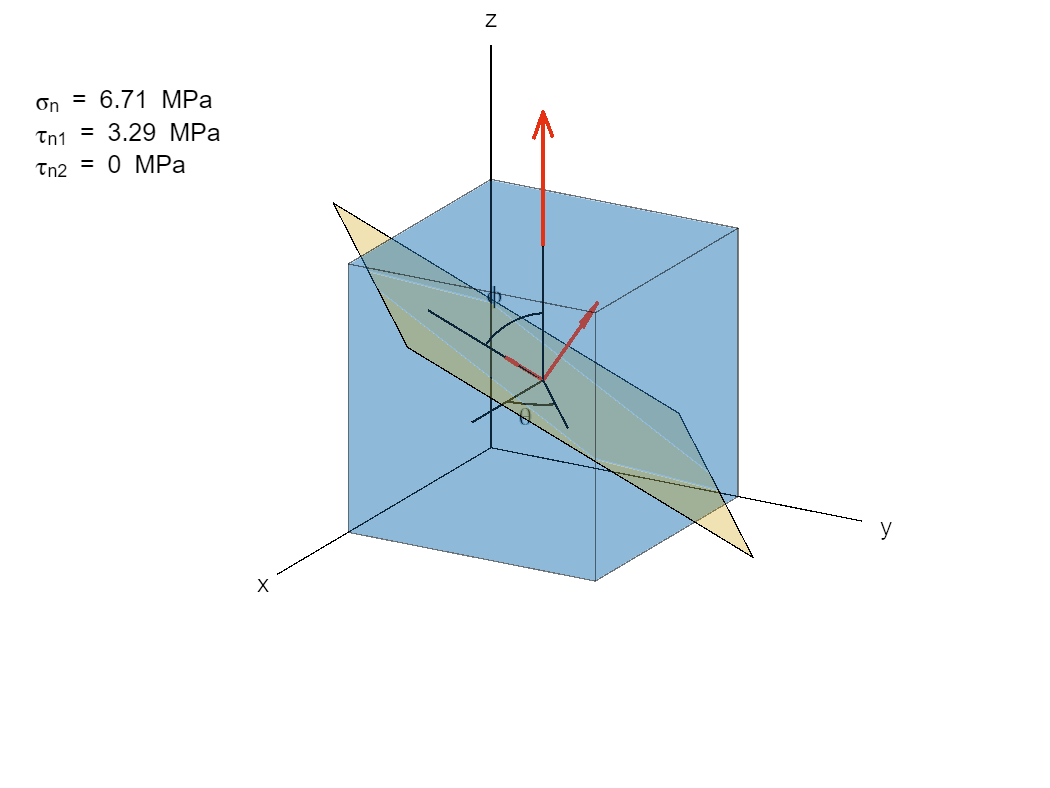

thetad  =40; % Degrees
phid    =55;  % Degrees
sigmaxx =0; % MPa
sigmayy =0; % MPa
sigmazz =10; % MPa
tauxy   =0; % MPa
tauxz   =0; % MPa
tauyz   =0; % MPa

plotStress3D(thetad,phid,sigmaxx,sigmayy,sigmazz,tauxy,tauxz,tauyz);

function plotStress3D(thetad,phid,sigmaxx,sigmayy,sigmazz,tauxy,tauxz,tauyz)

    % Plot parameters and definitions
    annotationColor = [0 0 0];
    vectorColor = [230 50 20]/255; % Stress vector color
    rs = 0.5; % Half square side
    rp = 1; % Radius of plane circle
    rtheta = rp/4; % Theta annotation radius
    sc = 0.05; % Scale factor for stress arrows
    arrlw = 1.5; % Arrow line width
    headSize = 0.3;
    axLims = [-1 1 -1 1 -1 1]*0.8;
    viewAngle = [120 20];
    % Cube side colors
    c = [50 161 245]/255/1.35;
    cubeAlpha = 0.3;
    cubeEdgeAlpha = 0.5;
    % Plane
    planeRadius = 0.75;
    planeColor = [245 189 0]/255/1.2;
    planeAlpha = 0.3;
    planeVertices = [-1 0 -1; 1 0 -1; 1 0 1; -1 0 1]*planeRadius;
    planeFaces = [1 2 3 4 1];

    % Calculations
    % Cutting plane
    np = [0 1 0]'; % Normal vector
    R1 = [1 0 0; 0 cosd(phid) -sind(phid); 0 sind(phid) cosd(phid)];
    R2 = [cosd(thetad) -sind(thetad) 0; sind(thetad) cosd(thetad) 0; 0 0 1];
    for k = 1:size(planeVertices,1)
        planeVertices(k,:) = (R2*R1*(planeVertices(k,:))')';
    end
    N = R2*R1*np;
    Nperp1 = R2*R1*[1 0 0]';
    Nperp2 = R2*R1*[0 0 1]';

    % theta annotation positions
    xAxisLine = [0 0 0; rs 0 0]';
    for k = 1:size(xAxisLine,2)
        xyzLineTheta(:,k) = R2*xAxisLine(:,k);
    end
    thd = linspace(0,thetad,100)';
    xyzCircTheta = rtheta*[cosd(thd),sind(thd),0*thd];
    xThetaText = 1.5*rtheta*cosd(thetad/2);
    yThetaText = 1.5*rtheta*sind(thetad/2);
    zThetaText = 0;
    
    % phi annotation positions
    zAxisLine = [0 0 0; 0 0 rs]';
    for k = 1:size(zAxisLine,2)
        xyzLinePhi(:,k) = R2*R1*zAxisLine(:,k);
    end
    phidVec = linspace(0,phid,100)';
    xyzCircPhi= rtheta*[sind(phidVec)*sind(thetad),-cosd(thetad)*sind(phidVec),cosd(phidVec)];
    xPhiText = 1.5*rtheta*sind(phid/2)*sind(thetad);
    yPhiText = -1.5*rtheta*cosd(thetad)*sind(phid/2);
    zPhiText = 1.5*rtheta*cosd(phid/2);
    
    % Stress tensor
    S = [sigmaxx, tauxy,   tauxz;
         tauxy,  sigmayy, tauyz;
         tauxz,  tauxy,   sigmazz];
    % Normal stress
    sigman = N'*S*N;

    % Shear stresses (CHECK THIS! NEEDS A REFERENCE OR HAVE TO DERIVE IT/TEST IT)
    % 66666666666666666666666666666666666666666666666666666666666666666666666666
    tauN1 = Nperp1'*S*Nperp1;
    tauN2 = Nperp2'*S*Nperp2;
    % end 666
    
    % Cube
    [vertices,faces,normals] = cubeValues(); 
    vertices = vertices - rs;

    % Stress vectors (exterior)
    xs = [rs rs rs  0  0  0  0  0  0 ];
    ys = [ 0  0  0  rs rs rs 0  0  0 ];
    zs = [ 0  0  0  0  0  0  rs rs rs];
    us = sc*[sigmaxx 0 0 tauxy 0 0 tauxz 0 0];
    vs = sc*[0 tauxy 0 0 sigmayy 0 0 tauyz 0];
    ws = sc*[0 0 tauxz 0 0 tauyz 0 0 sigmazz];
    % Stress vectors (plane)
    xs = [xs 0 0 0];
    ys = [ys 0 0 0]; 
    zs = [zs 0 0 0];
    us = [us sc*sigman*N(1) sc*tauN1*Nperp1(1) sc*tauN2*Nperp2(1)];
    vs = [vs sc*sigman*N(2) sc*tauN1*Nperp1(2) sc*tauN2*Nperp2(2)];
    ws = [ws sc*sigman*N(3) sc*tauN1*Nperp1(3) sc*tauN2*Nperp2(3)];

    % Create plot
    cla
    set(gca,"Clipping","off")
    patch("Vertices",vertices,"Faces",faces,"EdgeAlpha",cubeEdgeAlpha,...
          "FaceColor","Flat","FaceVertexCData",c,"FaceAlpha",cubeAlpha);
    patch("Vertices",planeVertices,"Faces",planeFaces,...
          "FaceColor","Flat","FaceVertexCData",planeColor,"FaceAlpha",planeAlpha);
    axis equal
    axis([-1,1,-1,1,-1,1]*1 + rs)

%     patch([-1 1 1 -1]*rs,[-1 -1 1 1]*rs,c) % Element square patch
    hold on
    
    % Theta annotation with lines
    plot3(xAxisLine(1,:),xAxisLine(2,:),xAxisLine(3,:),"Color",annotationColor,"LineWidth",0.85)
    plot3(xyzLineTheta(1,:),xyzLineTheta(2,:),xyzLineTheta(3,:),"Color",annotationColor,"LineWidth",0.85)
    plot3(xyzCircTheta(:,1),xyzCircTheta(:,2),xyzCircTheta(:,3),"Color",annotationColor,"LineWidth",0.85)
    text(xThetaText,yThetaText,zThetaText,...
        "\theta","Color",annotationColor,"HorizontalAlignment","center")
   
    % Phi annotation with lines
    plot3(zAxisLine(1,:),zAxisLine(2,:),zAxisLine(3,:),"Color",annotationColor,"LineWidth",0.85)
    plot3(xyzLinePhi(1,:),xyzLinePhi(2,:),xyzLinePhi(3,:),"Color",annotationColor,"LineWidth",0.85)
     plot3(xyzCircPhi(:,1),xyzCircPhi(:,2),xyzCircPhi(:,3),"Color",annotationColor,"LineWidth",0.85)
    text(xPhiText,yPhiText,zPhiText,...
        "\phi","Color",annotationColor,"HorizontalAlignment","center")

    % Stress arrows
    quiver3(xs,ys,zs,us,vs,ws,"Color",vectorColor,...
        "LineWidth",arrlw,"MaxHeadSize",headSize,"Autoscale","off")

    % Display stress values
    annotation("textbox",[0.02,0.6,0.3,0.3],"String",...
        "\sigma_n = " + num2str(sigman,3) + " MPa" + newline + ...
        "\tau_{n1} = " + num2str(tauN2,3) + " MPa" + newline + ...
        "\tau_{n2} = " + num2str(tauN1,3) + " MPa",...
        "EdgeColor","None")

    % Axes
    plot3([0 1 NaN 0 0 NaN 0 0]*rs*3-rs,[0 0 NaN 0 1 NaN 0 0]*rs*3-rs,[0 0 NaN 0 0 NaN 0 1]*rs*3-rs,'k')
    text(rs*3.2-rs, -rs, -rs, "x","HorizontalAlignment","center","VerticalAlignment","middle")
    text(-rs, rs*3.2-rs, -rs, "y","HorizontalAlignment","center","VerticalAlignment","middle")
    text(-rs, -rs, rs*3.2-rs, "z","HorizontalAlignment","center","VerticalAlignment","middle")

    % Axis settings
    hold off
    axis equal
    axis(axLims)
    axis off
    view(viewAngle)

end

function [vertices,faces,normals] = cubeValues()
    vertices = [0 0 0; 1 0 0; 1 1 0; 0 1 0;
                0 0 1; 1 0 1; 1 1 1; 0 1 1];
    faces = [1 2 3 4 1; 5 6 7 8 5; 1 2 6 5 1; 
             3 4 8 7 3; 1 4 8 5 1; 2 3 7 6 2];
    normals = [0 0 -1; 0 0 1; 0 -1 0; 0 1 0; -1 0 0; 1 0 0];
end

%#ok<*ASGLU>
%#ok<*INUSD> 